姓名：莊璧如 學號：111321534

ex1

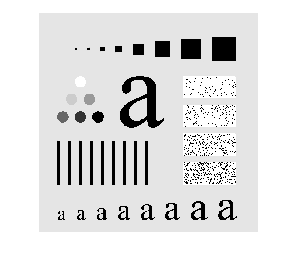

im=imread('Fig3.35(a).jpg');
imshow(im,[])

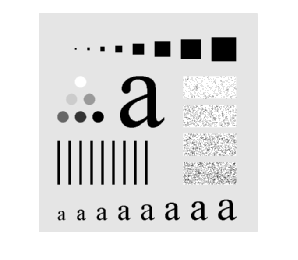

a=ones(3,3)/9;
i2=filter2(a,im,'same'); 
imshow(i2,[])

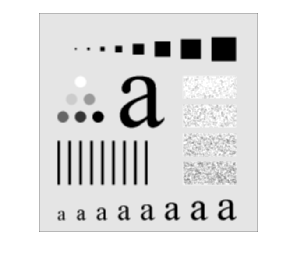

a=ones(5,5)/25;
i3=filter2(a,im,'same'); 
imshow(i3,[])

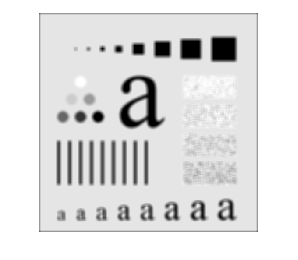

a=ones(9,9)/81;
i4=filter2(a,im,'same'); 
imshow(i4,[])

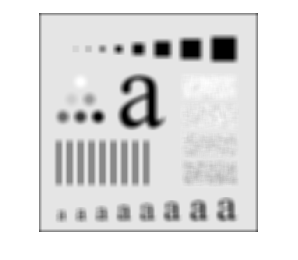

a=ones(15,15)/225;
i5=filter2(a,im,'same'); 
imshow(i5,[])

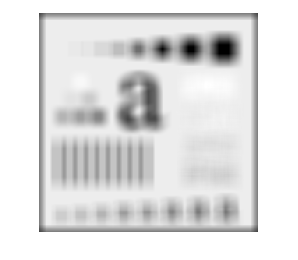

a=ones(35,35)/1225;
i6=filter2(a,im,'same'); 
imshow(i6,[])

ex2

I=imread('ckt-board.tif');
J=imnoise(I, 'salt & pepper', 0.1);
J=medfilt2(J)

J = 448×464 uint8 matrix
     0   248     0   248   248   248   248   248   248   247   247   247   248   247   248   248   248   248   248   248   248   248   248   248   248   248   248   249   249   247   247   247   247   247   247   247   248   248   248   248   248   248   248   248   248   248   248   248   248   248
   248   248   248   248   248   248   248   248   248   247   248   248   248   248   248   248   248   248   248   248   248   249   249   249   248   249   249   249   249   247   247   247   247   247   247   247   248   248   248   248   248   248   248   248   248   248   248   248   248   248
   248   248   248   248   248   248   248   247   247   247   248   248   248   248   249   249   248   248   248   248   249   249   249   249   249   249   249   249   249   248   247   247   247   247   247   247   248   248   248   248   248   248   248   248   248   248   248   248   248   248
   248   248   248   248   248   248   247   247   247   248   249   249

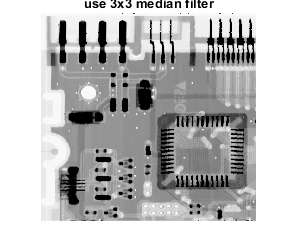

figure, imshow(J)
title('use 3x3 median filter')

a=ones(3,3)/9;
J2=filter2(a,I,'same')

J2 =   110.2222  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.2222  165.1111  165.0000  165.0000  164.8889  165.2222  165.5556  165.8889  165.7778  165.5556  165.4444  165.3333  165.3333  165.5556  165.7778  165.7778  165.5556  165.3333  165.5556  165.8889  166.2222  165.7778  165.2222  164.6667  164.7778  164.8889  165.1111  165.3333  165.2222  165.2222  165.1111  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333  165.3333
  165.3333  248.0000  248.0000  248.0000  248.0000  248.0000  247.8889  247.6667  247.4444  247.3333  247.4444  247.4444  247.8889  248.2222  248.5556  248.3333  248.0000  247.6667  247.4444  247.2222  247.7778  248.3333  248.7778  248.5556  248.3333  248.5556  248.8889  249.2222  248.5556  247.7778  247.0000  247.1111  247.2222  247.4444  247.5556  247.4444  247.5556  247.6667  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  248.0000  24

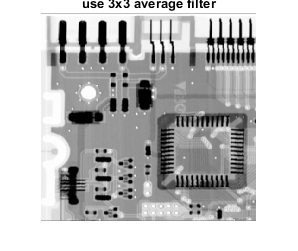

imshow(J2,[])
title('use 3x3 average filter')

ex3

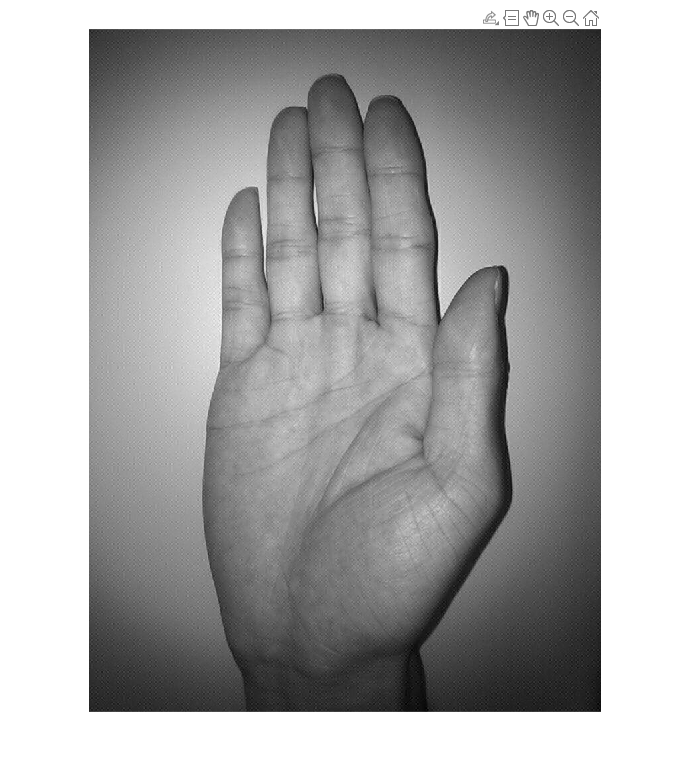

x =   332.7500
  337.2500
  337.2500


y =   613.0000
  673.0000
  674.5000


palm=imread('palm2016.jpg');
imshow(palm,[])
[x,y]=getline()

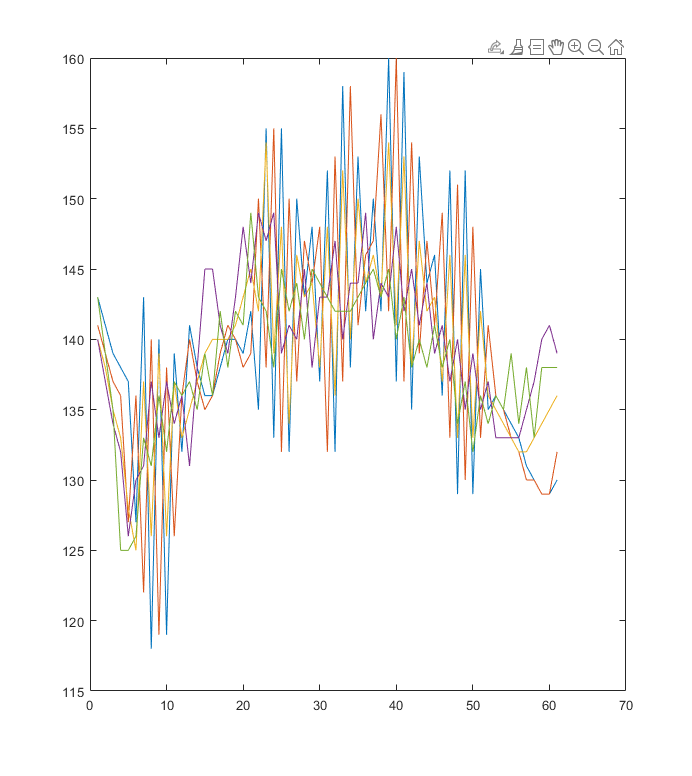

plot(palm(uint16(y(1)):uint16(y(2)),uint16(x(1)):uint16(x(2))))

ex4

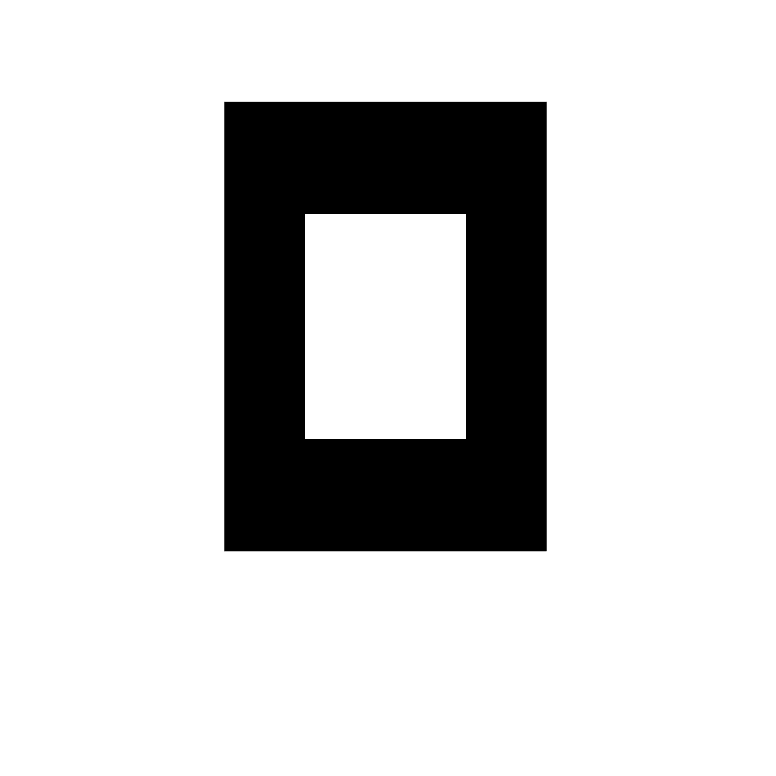

A=zeros(128,128);
A(33:96,33:96)=255*ones(64,64);
imshow(A,[])

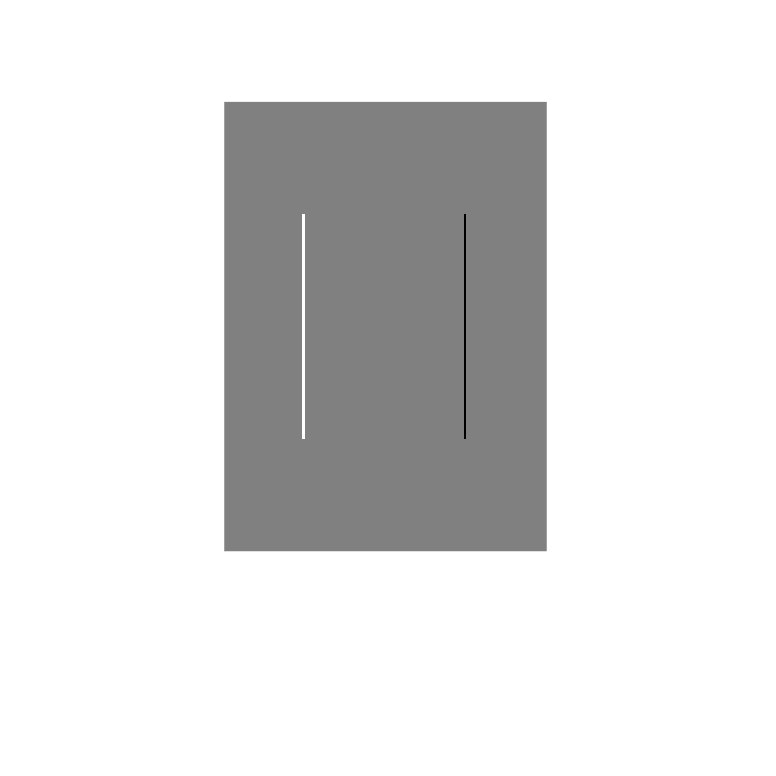

h=[-1,1];
a1=filter2(h,A,'same');
imshow(a1,[])

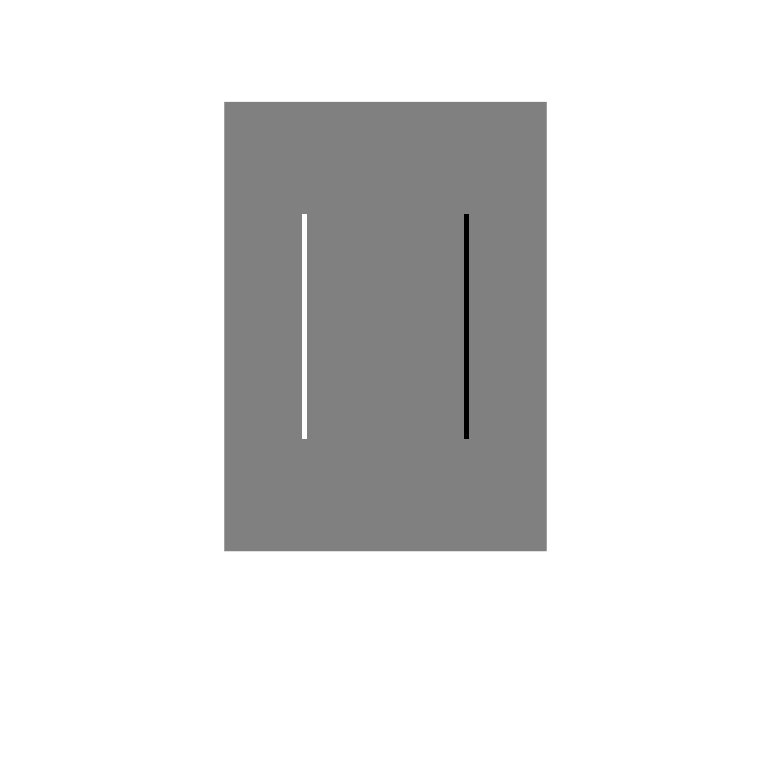

h=[-1,0,1];
out=filter2(h,A,'same');
imshow(out,[])